# Derivative control to explain phase-leading behavior in *Drosophila* head movements

clear; close all; clc
syms s I c k K_p K_d K_i a_2 tau K
assume([I c k s]>=0)
assume([I c k],'real')
freqRange = logspace(-1,2,10000);

## Contol Framework

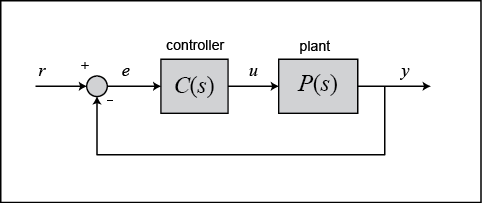

### Plant

Natural Frequency (rad/s)

wn = 50;

Damping Ratio

z = 1.2;

Head inertia about rotation point (kg*m^2)

I = 1;

Head stiffness (N*m/rad)

k = wn^(2)*I;

Head critical damping (N*m*s/rad)

cc = 2*sqrt(k*I);

Head damping (N*m*s/rad)

c = z*cc;
P(s) = 1/(I*s^(2) + c*s + k)

$$P(s) = \frac{1}{s^{2}+120\,s+2500}$$

### Nominal Controller

C1(s) = sym(0.1)

$$C1(s) = \frac{1}{10}$$

### Closed-Loop Model


$$G\left(s\right)=\frac{Y\left(s\right)}{R\left(s\right)}=\frac{P\left(s\right)C\left(s\right)}{1+P\left(s\right)C\left(s\right)}$$


G(s) = 1000*collect(simplify(P(s)*C1(s)/(1 + P(s)*C1(s))),s)

$$G(s) = \frac{1000}{10\,s^{2}+1200\,s+25001}$$

[MAG{1},PHS{1},FREQ{1}] = bode(sym2tf(G(s)),freqRange);

## Derivative Controller Design

The controller is of the form


$$C\left(s\right)=K_p +K_d s$$


Kp = C1(s);
Kd = 0.2;

C2(s) = Kp + Kd*s

$$C2(s) = \frac{s}{5}+\frac{1}{10}$$

And the combined controller

C(s) = C2(s);

The new closed-loop model

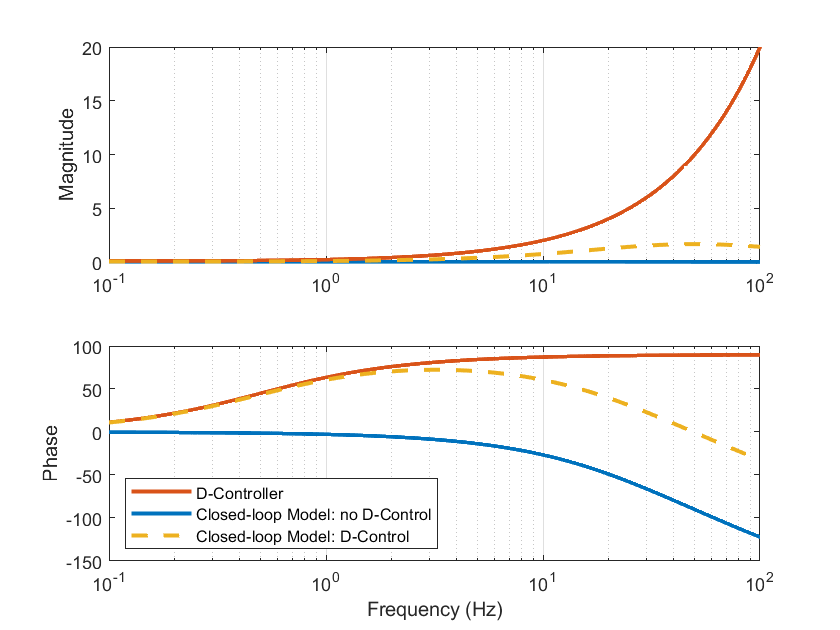

G(s) = 1000*simplify(expand(P(s)*C(s)/(1 + P(s)*C(s))));

[MAG{2},PHS{2},FREQ{2}] = bode(sym2tf(C(s)),freqRange);
[MAG{3},PHS{3},FREQ{3}] = bode(sym2tf(G(s)),freqRange);
figure (1) ; clf
h = gobjects(3,2);
for kk = 1:length(MAG)
    ax(1) = subplot(2,1,1);
    h(kk,1) = semilogx(FREQ{kk},squeeze(MAG{kk}),'LineWidth',2);
    hold on
    ylabel('Magnitude')
    
    ax(2) = subplot(2,1,2);
    h(kk,2) = semilogx(FREQ{kk},squeeze(PHS{kk}),'LineWidth',2);
    hold on
    ylabel('Phase')
    xlabel('Frequency (Hz)')
end
set(ax,'XLim',10.^[-1 2],'XGrid','on')
set(h(3,:),'LineStyle','--')
leg = legend(h([2,1,3],2),'D-Controller','Closed-loop Model: no D-Control','Closed-loop Model: D-Control');
set(leg,'Location','southwest')